% 
% % Main function of PL detection and tracking by
% % Marker-Controlled Watershed Segmentation based on SAR
% %
% % Author: Mingyu Zhang V0.1
% 


% if exist(sarpath,"file")
%     load(sarpath);
%     fprintf(['====Data Load Success===\nSAR --> ' time '\n']);
% else
%     fprintf('Data Load Error......File Not Found...\n');
%     pause;
% end



## read data

clc;clear;close;
path='C:\Users\张铭宇\Desktop\cases good\';
sarname='S1A_EW_GRDM_1SDH_20141231T201906_20141231T202010_003968_004C69_6E39.SAFE';


filename=dir([path sarname '\measurement\']);titletime=sarname(18:30);
if length(filename)<=2 
    pause;
else
    i=3;%3-->hh 4-->hv
    filename=[filename(i).folder '\' filename(i).name];
end

tifinfo=geotiffinfo(filename);fprintf([tifinfo.ImageDescription '\n']);

Sentinel-1A EW GRD MR L1


tif=readgeoraster(filename);
res=5;
tifres=windowsmooth(tif,res); 
% tifres(tifres<1e-4)=nan;tifres(tifres>5*(nanmean(nanmean(tifres))))=nan;


lonx=tifinfo.TiePoints.WorldPoints.X;laty=tifinfo.TiePoints.WorldPoints.Y;
row=(tifinfo.TiePoints.ImagePoints.Row+0.5)/res;col=(tifinfo.TiePoints.ImagePoints.Col+0.5)/res;
[gy,gx]=meshgrid(1:size(tifres,2),1:size(tifres,1));
lon=griddata(row,col,lonx,gx,gy);lat=griddata(row,col,laty,gx,gy);

tifress=tifres;
for i=6:size(tifres,1)-5
    for j=6:size(tifres,2)-5
        if isnan(tifres(i,j))
            tifress(i-5:i+5,j-5:j+5)=nan;
        end
    end
end

db_hh=tifress;sarlon=lon;sarlat=lat;lono=lon;lato=lat;hho=tifress;
clear lonx laty row col gy gx tifres res tif tifress lon lat tifinfo

## orginal image

hho=db_hh;lono=sarlon;lato=sarlat;
sout=abs(hho)/max(max(abs(hho)));
g=10*log10(sout+eps);
g(g<-50)=nan;
mn=nanmean(g);x=1:length(mn);mn=interp1(x(~isnan(mn)),mn(~isnan(mn)),x);
k=polyfit(x(~isnan(mn)),mn(~isnan(mn)),3);y=k(1)*x.^3+k(2)*x.^2+k(3)*x+k(4);
hho=g-y;
hho=etopomask(hho,lono,lato);

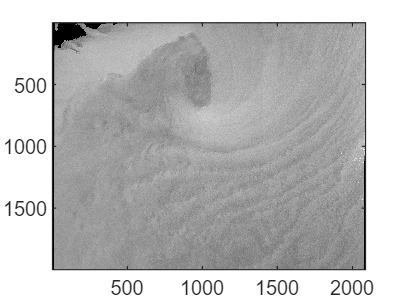

figure;
imagesc(hho);colormap(gray);


% hho=etopomask(hho,lono,lato);
% hho(isnan(hho))=-1;
% hho=ard_dlt(hho,hho,40,-1,-1);
% hho(hho==-1)=nan;hho=rescale(hho);
%   %imshow(hho);
% mn=nanmean(hho);x=1:length(mn);mn=interp1(x(~isnan(mn)),mn(~isnan(mn)),x);
% k=polyfit(x(~isnan(mn)),mn(~isnan(mn)),3);y=k(1)*x.^3+k(2)*x.^2+k(3)*x+k(4);
% hho=hho-y;
% hho=rescale(hho);hho=imadjust(hho);hho(isnan(hho))=1;
% 



m_proj('Mercator','lon',[min(min(sarlon))-(max(max(sarlon))-...
    min(min(sarlon)))/4 max(max(sarlon))+(max(max(sarlon))-...
    min(min(sarlon)))/4],'lat',[min(min(sarlat))-(max(max(sarlat))-...
    min(min(sarlat)))/4 max(max(sarlat))+(max(max(sarlat))-...
    min(min(sarlat)))/4]);
hold on;
m_pcolor(sarlon(10:end-10,10:end-10),sarlat(10:end-10,10:end-10),db_hh(10:end-10,10:end-10))
shading flat
colormap gray
m_gshhs_l;
xlabel('Longitude','FontWeight','bold',...
    'FontSize',14,...
    'FontName','times new roman');
ylabel('Latitude','FontWeight','bold',...
    'FontSize',14,...
    'FontName','times new roman');

m_grid('box','fancy','tickdir','in','linestyle','none');

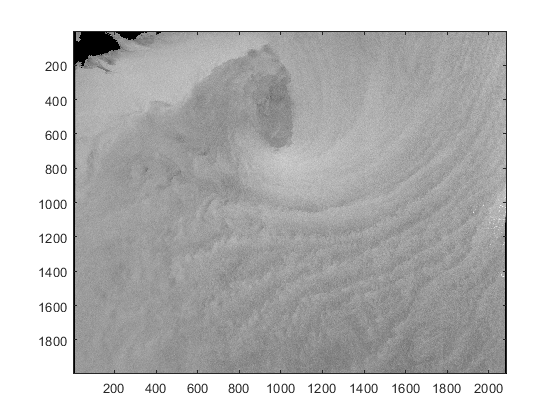

close all;
imagesc(hho);colormap(gray);
[ay,ax]=ginput;

ay=fix(ay);ax=fix(ax);close;
db_black=db_hh(min(ax):max(ax),min(ay):max(ay));
db_black=rescale(db_black);
db_black(isnan(db_black))=0;
sarlon=sarlon(min(ax):max(ax),min(ay):max(ay));
sarlat=sarlat(min(ax):max(ax),min(ay):max(ay));


net = denoisingNetwork('dncnn');
db_black(1:fix(size(db_black,1)/2),:)=denoiseImage(db_black(1:fix(size(db_black,1)/2),:),net);
db_black(fix(size(db_black,1)/2)+1:end,:)=denoiseImage(db_black(fix(size(db_black,1)/2)+1:end,:),net);
% db_black = denoiseImage(db_black,net);

db_black_top=etopomask(db_black,sarlon,sarlat);

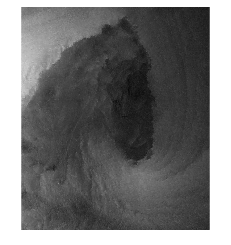

imshow(db_black_top)


db_im=db_black_top;%%
db_im(db_im==0)=nan;
db_im=rescale(db_im);
db_im(isnan(db_im))=1;
% db_im=ard_dlt(db_im,db_im,20,1,1);  %imshow(db_im)

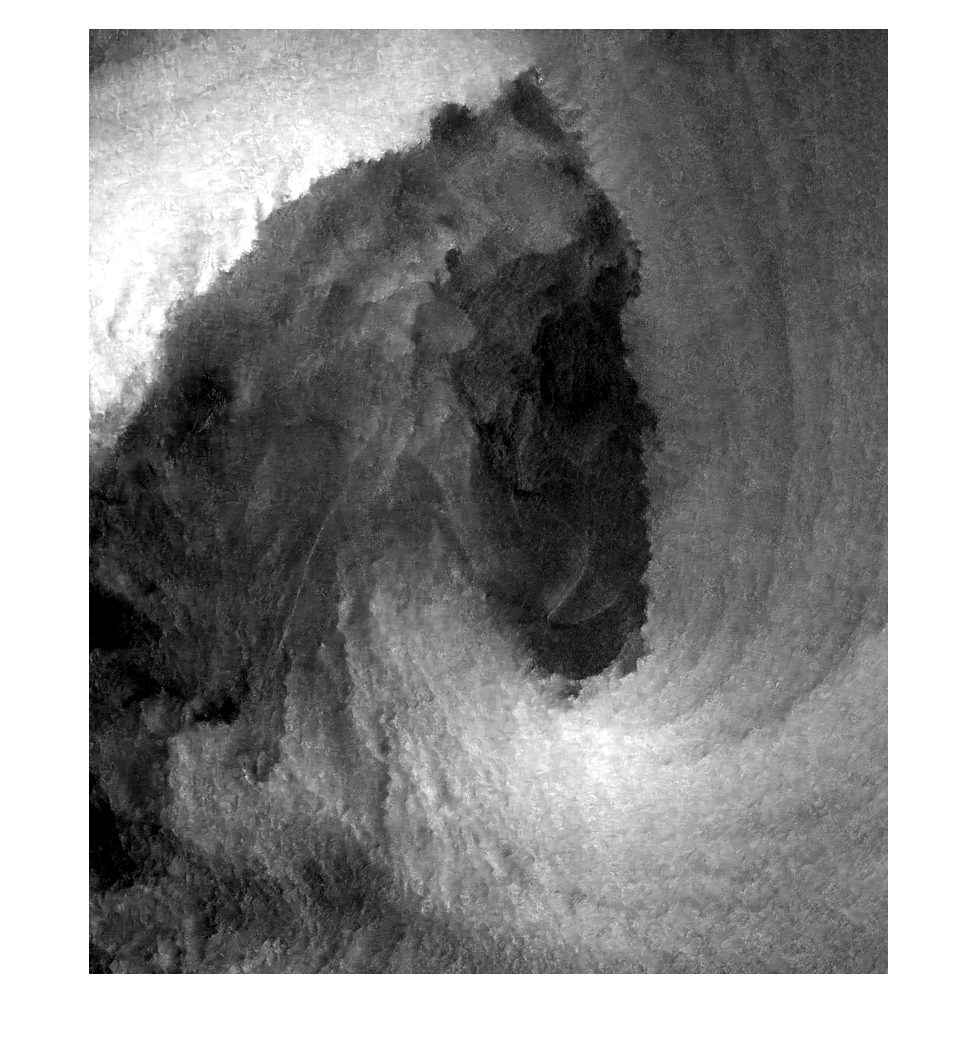

db_im(db_im==1)=nan;
mn=nanmean(db_im);x=1:length(mn);mn=interp1(x(~isnan(mn)),mn(~isnan(mn)),x);
k=polyfit(x(~isnan(mn)),mn(~isnan(mn)),3);y=k(1)*x.^3+k(2)*x.^2+k(3)*x+k(4);
db_im=db_im-y;
db_im=rescale(db_im);db_im=imadjust(db_im);db_im(isnan(db_im))=1;
figure;

imshow(db_im);close;
lon=sarlon;
lat=sarlat;

m_proj('lambert','lon',[min(min(sarlon))-(max(max(sarlon))-...
    min(min(sarlon)))/4 max(max(sarlon))+(max(max(sarlon))-...
    min(min(sarlon)))/4],'lat',[min(min(sarlat))-(max(max(sarlat))-...
    min(min(sarlat)))/4 max(max(sarlat))+(max(max(sarlat))-...
    min(min(sarlat)))/4]);
hold on;
colormap(gray(64));
db=m_pcolor(lon,lat,db_im);shading flat;
m_gshhs_i('patch',[.6 .7 .6],'edgecolor','none');
m_grid('box','fancy','tickdir','in');
xlabel('Longitude','FontWeight','bold','FontSize',14,...
    'FontName','times new roman');
ylabel('Latitude','FontWeight','bold','FontSize',14,...
    'FontName','times new roman');
title(['SAR ' titletime],'FontName','Times New Roman','FontSize',14,'FontWeight','bold');

## MCWS_main

sarim=db_im;lon=lon;lat=lat;time=titletime;
atmtkbyspd="no";
% step 1:Use the pre-processed SAR image to calculate
% gradient magnitude to obtain a segmentation function.
gmag=imgradient(sarim);
% imshow(gmag);title('Gradient Magnitude');

% step 2:Compute opening-closing reconstruction image
ocbr=imopclrecon(sarim,fix(length(sarim)/50));
% imshow(ocbr);title('opening-closing by reconstruction');

% step 3:Compute Foreground Markers
fgdmk=imfgdmk(ocbr);
% imshow(fgdmk);title('foreground markers');

% step 4:Compute Background Markers
bgdmk=imbgdmk(ocbr);
% imshow(bgdmk);title('background markers');

% step 5:Modify gradient magnitude by fgdmk and bgdmk
gmag_mod=imimposemin(imgradient(imopclrecon(sarim, fix(length(sarim)/50))), bgdmk | fgdmk);
% gmag_mod=imimposemin(sarim, bgdmk | fgdmk);
% gmag_mod=imimposemin(imgradient(imopclrecon(sarim, 1)), bgdmk | fgdmk);


% imshow(gmag_mod);title('modified gradient magnitude');

% step 6:Marker-controlled watershed segmentation
% matrix 'L' is the result of MCWS; '0' is the meaning of binaray
% different number means different results of segmentation
mcws = watershed(gmag_mod);

% labels figure
labels = imdilate(mcws==0,ones(10,10)) + 2*bgdmk + 3*fgdmk;
% figure;
% wtershedim=imshow(labeloverlay(sarim,labels));
% title({'marker-controlled watershed segmentation' ; time});

close all;
% automatic or manual find the index of segmentation area
if atmtkbyspd=="yes"
    areaindex=mcwsatmtk(sarim,mcws);    
else
    areaindex=mcwsmn(sarim,mcws,fgdmk);
end

% compute the location of the center area
[ctrlon,ctrlat]=mcwsctrloc(lon,lat,mcws,areaindex,fgdmk);

% savepath=[path titletime '\'];mkdir(savepath);
% lonax=[min(min(lon))-(max(max(lon))-min(min(lon)))/4 
%     max(max(lon))+(max(max(lon))-min(min(lon)))/4];
% latax=[min(min(lat))-(max(max(lat))-min(min(lat)))/4 
%     max(max(lat))+(max(max(lat))-min(min(lat)))/4];
% 
% imagesc(db_im);colormap("gray");
% [ay,ax]=ginput;
% ay=fix(ay);ax=fix(ax);
% ctrlon=lon(ax,ay);ctrlat=lat(ax,ay);
% close all;figure;
% m_proj('lambert','lon',[min(min(lon))-(max(max(lon))-...
%     min(min(lon)))/4 max(max(lon))+(max(max(lon))-...
%     min(min(lon)))/4],'lat',[min(min(lat))-(max(max(lat))-...
%     min(min(lat)))/4 max(max(lat))+(max(max(lat))-...
%     min(min(lat)))/4]);
% hold on;
% m_pcolor(lon,lat,sarim);
% m_scatter(ctrlon,ctrlat,'x','linewidth',2);
% shading flat;colormap gray;
% m_gshhs_i('patch',[.6 .7 .6],'edgecolor','none');
% xlabel('Longitude','FontWeight','bold',...
%     'FontSize',14,...
%     'FontName','times new roman');
% ylabel('Latitude','FontWeight','bold',...
%     'FontSize',14,...
%     'FontName','times new roman');
% m_grid('box','fancy','tickdir','in','linestyle','none');
% title(['SAR ' titletime],'FontName','Times New Roman','FontSize',14,'FontWeight','bold');
% print(gcf,'-dpng','-r600',strcat(savepath,titletime,' sar'));
% plcenter{1}.name='sar';
% plcenter{1}.lon=ctrlon;
% plcenter{1}.lat=ctrlat;
% plcenter{1}.time=titletime;

## imshow

savepath=[path titletime '\'];mkdir(savepath);
[~,londb,latdb,~,db11,~,~,~]=read_S1AB([path sarname]);
% [~,londb,latdb,~,db11,~,~,~]=read_S1AB('C:\Users\张铭宇\Desktop\cases good\results\cases\20141231T2019\S1A_EW_GRDM_1SDH_20141231T201906_20141231T202010_003968_004C69_6E39.SAFE');
% ctrlon=plcenter{1}.lon;ctrlat=plcenter{1}.lat;
lonax=[min(min(londb))-(max(max(londb))-min(min(londb)))/20 
    max(max(londb))+(max(max(londb))-min(min(londb)))/20];
latax=[min(min(latdb))-(max(max(latdb))-min(min(latdb)))/20  
    max(max(latdb))+(max(max(latdb))-min(min(latdb)))/20 ];
% 
db11(isinf(db11))=nan;
mn=nanmean(db11);x=1:length(mn);mn=interp1(x(~isnan(mn)),mn(~isnan(mn)),x);
k=polyfit(x(~isnan(mn)),mn(~isnan(mn)),3);y=k(1)*x.^3+k(2)*x.^2+k(3)*x+k(4);
db=db11-y+mean(y);


close all;figure;
m_proj('lambert','lon',lonax,'lat',latax);
hold on;
m_pcolor(londb,latdb,db(7:end,:));
m_pcolor(londb(7:end,:),latdb(7:end,:),db(7:end,:));
sc=m_scatter(ctrlon,ctrlat,'rx','linewidth',3);
sc.SizeData=125;
shading flat;colormap gray;
m_gshhs_i('patch',[.6 .7 .6],'edgecolor','none');
xlabel('Longitude','FontWeight','bold',...
    'FontSize',14,...
    'FontName','times new roman');
ylabel('Latitude','FontWeight','bold',...
    'FontSize',14,...
    'FontName','times new roman');
m_grid('box','fancy','tickdir','in','linestyle','none');
title(['SAR ' titletime],'FontName','Times New Roman','FontSize',14,'FontWeight','bold');
print(gcf,'-dpng','-r600',strcat(savepath,titletime,' sar'));
savefig(gcf,strcat(savepath,titletime,' sar.fig'));
plcenter{1}.name='sar';
plcenter{1}.lon=ctrlon;
plcenter{1}.lat=ctrlat;
plcenter{1}.time=titletime;

sarlon=lon;sarlat=lat;

函数或变量 'lon' 无法识别。

clearvars -except titletime sarlon sarlat path lonax latax plcenter savepath
save([savepath titletime ' sar lonlat.mat'],'-mat');

run ZSthin_main
close all;